# Radar Signal Processing

## Create Platforms

clc
close all
clear variables
[scenario,targetPlatform,radarPlatform] = helperCreatePlatforms;

## Set up Radar Transceiver

radar = radarTransceiver();

% update transmitter gain
radar.Transmitter = phased.Transmitter("PeakPower",2e3);

% update transmit and receive antenna arrays
antArray = phased.ULA("NumElements",32,"ElementSpacing",0.015);
antArray.Element = phased.CosineAntennaElement;
radar.TransmitAntenna = phased.Radiator("Sensor",antArray,"OperatingFrequency",9.5e9);
radar.ReceiveAntenna = phased.Collector("Sensor",antArray,"OperatingFrequency",9.5e9);

figure
% display transmit pattern
pattern(radar.TransmitAntenna.Sensor,radar.TransmitAntenna.OperatingFrequency, ...
    -180:180, ... % azimuth range
    0, ... % elevation cut
    "Type", "directivity");

**Questions: **

- Why do we have two sided directivity pattern?

- How can we convert this two sided directivity pattern to one sided directivity pattern?

*            Check documentation for *[*phased.CosineAntennaElement*](https://www.mathworks.com/help/phased/ref/phased.cosineantennaelement-system-object.html)* and *[*phased.IsotropicAntennaElement*](https://www.mathworks.com/help/phased/ref/phased.isotropicantennaelement-system-object.html)

## Adjust the TX and RX Arrays

% set sampling rate
samplingRate = 1e7; % 10 MHz
% set false alarm rate
pfa = 1e-5;

% change antenna elements to CosineAntennaElement
radar.TransmitAntenna.Sensor.Element = phased.CosineAntennaElement;
radar.ReceiveAntenna.Sensor.Element = phased.CosineAntennaElement;

% update waveform 
radar.Waveform = phased.RectangularWaveform;
radar.Waveform.PulseWidth = 2e-6;
radar.Waveform.SampleRate = samplingRate;
radar.Waveform.PRF = 10e3;

% update receiver
radar.Receiver.SampleRate = samplingRate;

% add radar sensor to platform
radarPlatform.Sensors = radar;

## Generate Data Cube

% create data cube
nRangeSamples = round((1/radar.Waveform.PRF) / (1/radar.Receiver.SampleRate));
nAntenna = radar.TransmitAntenna.Sensor.NumElements;
nPulses = 64;
dataCube = zeros(nRangeSamples,nAntenna,nPulses);

% setup simulation loop for one burst
iter = 1;
while advance(scenario) && iter <= nPulses
    targets = targetPoses(radarPlatform);
    dataCube(:,:,iter) = radar(targets,scenario.SimulationTime);
    iter = iter + 1;
end

figure
% Visualize one channel (from a particular RX antenna) of the data cube
nchan = 19;
waterfall(squeeze(abs(dataCube(:,nchan,:))))
title("Channel "+nchan)
xlabel("Pulses (slow time)")
ylabel("Samples (fast time)")
zlabel("Magnitude")
view(-75,20)

## Signal Processing Chain

### 1. Range Processing

rangeProcessor = phased.RangeResponse("RangeMethod","Matched filter", ...
    "SampleRate",radar.Receiver.SampleRate);
rangeProcessedIQ = rangeProcessor(dataCube,radar.Waveform.getMatchedFilter);

figure
% Visualize one channel (from a particular RX antenna) of the data cube
nchan = 19;
waterfall(squeeze(abs(rangeProcessedIQ(:,nchan,:))))
title("Channel "+nchan)
xlabel("Pulses (slow time)")
ylabel("Samples (fast time)")
zlabel("Magnitude")
view(-75,20)

### 2. Range-Doppler Processing

pulseDopplerProcessor = phased.RangeDopplerResponse( ... 
   "RangeMethod","Matched filter", ...
   "SampleRate",radar.Receiver.SampleRate, ...
   "PRFSource","Property", ...
   "PRF",radar.Waveform.PRF, ...
   "OperatingFrequency",radar.ReceiveAntenna.OperatingFrequency,...
   "DopplerOutput","Speed");
[rangeDopProcessedIQ,rangeGates,dopplerBins] = pulseDopplerProcessor(dataCube,radar.Waveform.getMatchedFilter);

Display angle-doppler response of the detected range

rdscope = phased.RangeDopplerScope("IQDataInput",false,"ResponseUnits","magnitude",...
    "RangeLabel","Range (m)","DopplerLabel","Speed (m/s)");
rdmap = abs(squeeze(rangeDopProcessedIQ(:,nchan,:)));
rdscope(rdmap,rangeGates,dopplerBins)

## CFAR Detection

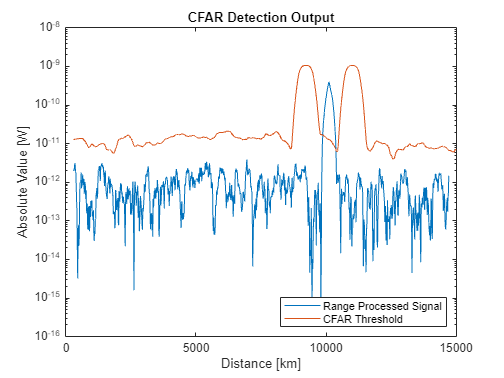

cfarDetector = phased.CFARDetector("Method","CA", ...
    "ProbabilityFalseAlarm",1e-6,"ThresholdOutputPort",true, ...
    "NumGuardCells",80,"NumTrainingCells",80);
[detIdx,th] = cfarDetector(abs(rangeProcessedIQ(:,1,1)).^2,1:size(rangeProcessedIQ,1));
helperDisplayCFAROutput(radar,nRangeSamples,rangeProcessedIQ,th)

**Question:** Why cannot we see detections for default values?

**Question:** How can we convert this to a simulation loop for the scenario?

#### ***NOTE:*** This exercise showcases that, input parameters are exteremly important to tune for the application.

## Range Estimation

maxNumTargets = 1;
rangeRstimator = phased.RangeEstimator("NumEstimatesSource","Property","NumEstimates",maxNumTargets); 
rngest = rangeRstimator(rangeProcessedIQ(:,nchan,1),rangeGates,find(detIdx > 0).')

rngest = 9.7657e+03

**Question**: How does the estimated range compare to the ground truth? 

[~,~,grndTruth] = cart2sph(targets.Position(1),targets.Position(2),targets.Position(3))

grndTruth = 1.0000e+04

function [scenario,targetPlatform,radarPlatform] = helperCreatePlatforms
scenario = radarScenario;
scenario.UpdateRate = 0;
% create target platform
[tPosX,tPosY,tPosZ] = sph2cart(0,0,10e3);
[targvx,tagvy,targvz] = sph2cart(0,0,50);
targetPlatform = platform(scenario);
targetPlatform.Trajectory = kinematicTrajectory("Position",[tPosX tPosY tPosZ], ...
    "Velocity",[targvx tagvy targvz]);
% create radar platform
radarPlatform = platform(scenario);
end

function helperDisplayCFAROutput(radar,nRangeSamples,rangeProcessedIQ,threshold)
blindRangeLimit = time2range(radar.Waveform.PulseWidth);
unambigRange = time2range(1/radar.Waveform.PRF);
rangeVec = linspace(blindRangeLimit,unambigRange,nRangeSamples);
figure
semilogy(rangeVec,abs(rangeProcessedIQ(:,1,1).^2),rangeVec,threshold);
% Add labels information to the figure
xlabel("Distance [km]")
ylabel("Absolute Value [W]")
title("CFAR Detection Output")
legend(["Range Processed Signal","CFAR Threshold"],"Location","southeast");
end